# Projekt 2

### Zadanie 1:

clear;
disp('Zadanie 1:')

Zadanie 1:


symulacja_obiektu15y_p2(0,0,0,0,0,0)

ans = 0

SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
fig = stairs(Y)

fig =   Stair with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×500 double]
              YData: [1×500 double]

  Show all properties


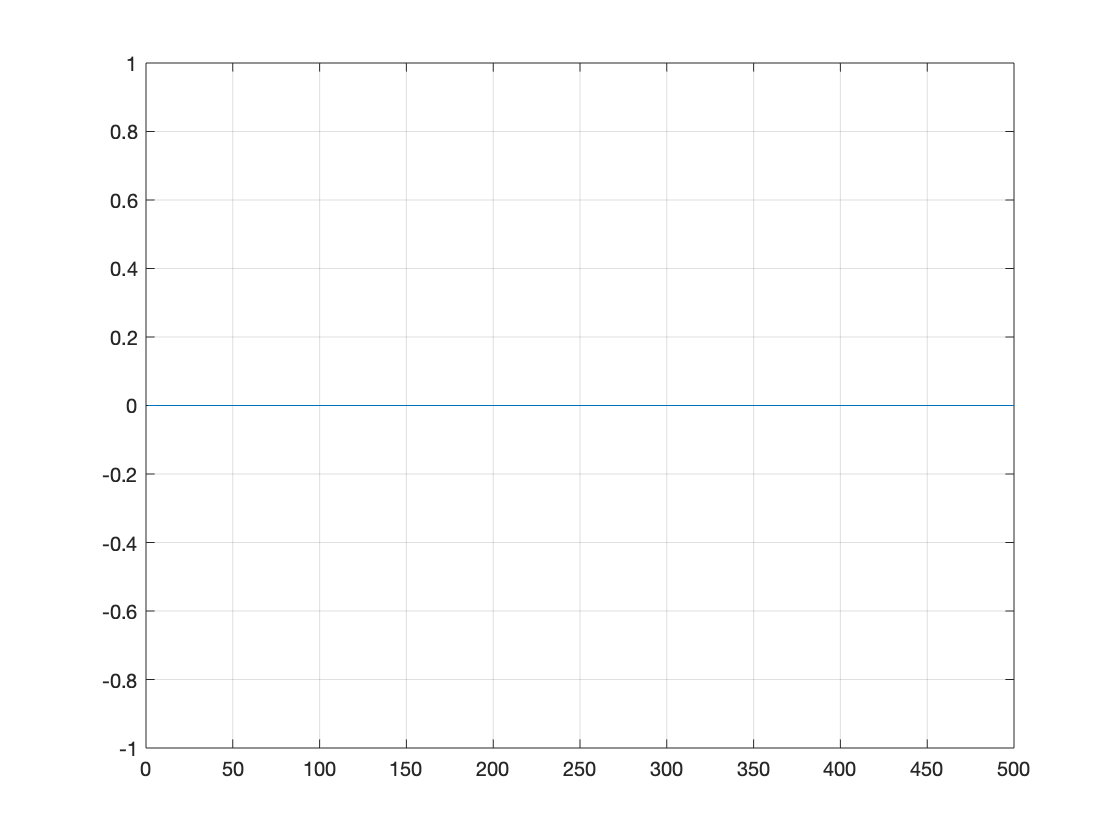

grid


writematrix([fig.XData; fig.YData]', 'txts/p2_zadanie1.txt', "Delimiter","tab")

### Zadanie 2:

clear;
disp('Zadanie 2:')

Zadanie 2:


Tor wejście wyjście

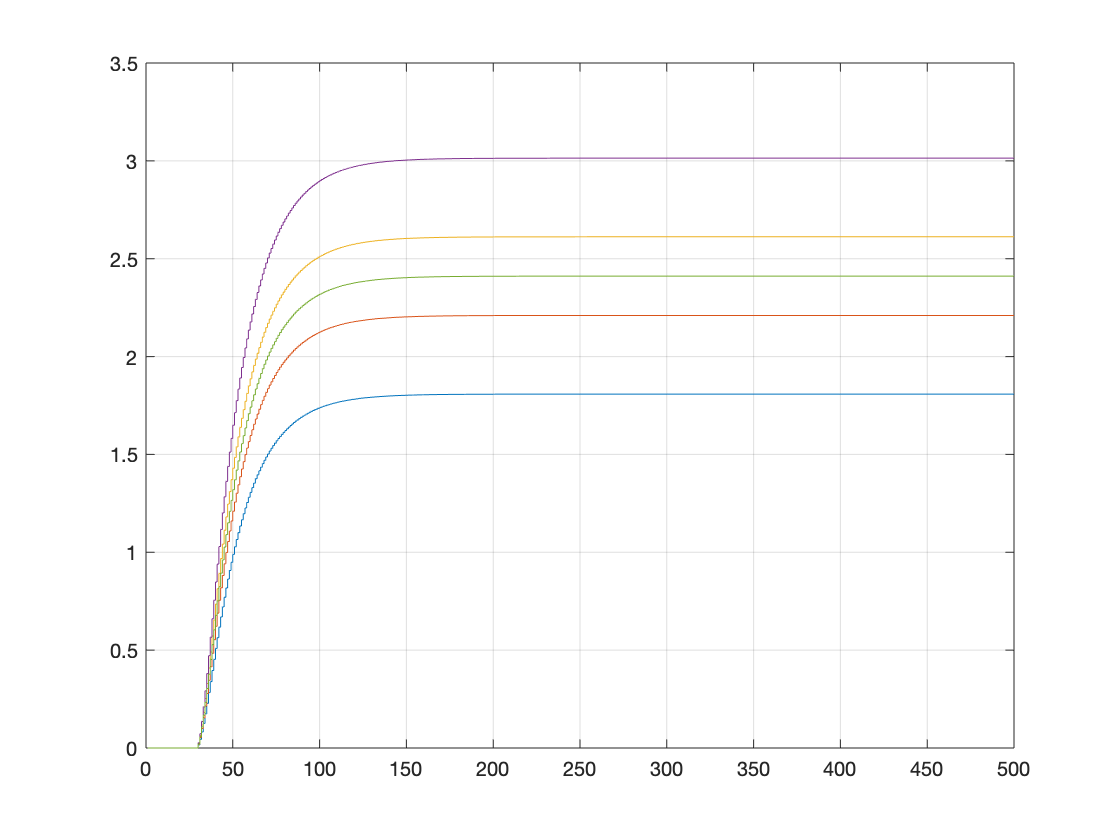

U_zad_zmiany = [0.9, 1.1, 1.3, 1.5, 1.2];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 10;

for p=1:length(U_zad_zmiany)
    U(STEP_MOMENT:end) = U_zad_zmiany(p);
    for k=30:SIM_LENGHT
        Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
            U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Tor zakłócenie-wyjście

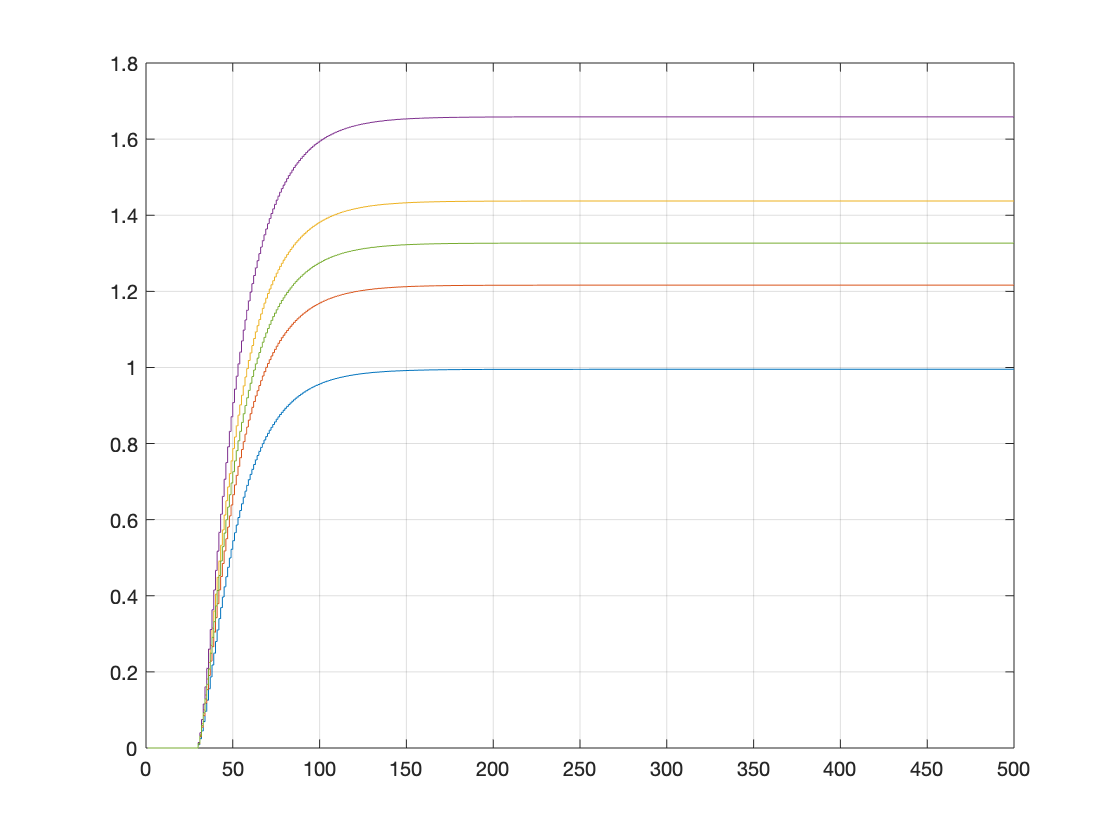

Z_zad_zmiany = [0.9, 1.1, 1.3, 1.5, 1.2];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 10;

for p=1:length(U_zad_zmiany)
    Z(STEP_MOMENT:end) = Z_zad_zmiany(p);
    for k=30:SIM_LENGHT
        Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
            U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Narysować charakterystykę statyczną procesu *y*(*u,z*). Czy właściwo- ści statyczne i dynamiczne procesu są (w przybliżeniu) liniowe? Jeżeli tak, określić wzmocnienie statyczne obu torów procesu. 	 

disp('Charakterystyka statyczna:')

Charakterystyka statyczna:


Y_stat = zeros(100,1);

U_zad = linspace(0.9, 1.5, 100)';
Z_zad = linspace(0.9, 1.5, 100)';
for i = 1:length(U_zad) % == length(Z_Zad)
    [Y, U] = get_YU(1.2, U_zad(i), SIM_LENGHT, STEP_MOMENT);
    Y_stat(i)= Y(SIM_LENGHT);
end

'symulacja_obiektu15Y_p1' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/piotr/Documents/studia/SEM5/PUST/21Z-PUST/P1
    /Users/piotr/Documents/studia/SEM5/PUST

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in ad1-3>get_YU (line 91)
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), U(k-11), Y(k-1), Y(k-2));

plot(U_zad, Y_stat)

Wzmocnienie statyczne to wspolczynnik kierunkowy prostej z wykresu


x = U_zad(:);
y = Y_stat(:);
X = [x.^0, x];
b = (X'*X)\X'*y;
Wzm_stat = b(2)

### Zadanie 3:

Przekształcić jedną z otrzymanych odpowiedzi w taki sposób, aby otrzymać odpowiedź skokową wykorzystywaną w algorytmie DMC, tzn. zestaw liczb s1, s2, . . . (przy skoku jednostkowym sygnału sterującego: od chwili k = 0 włącznie sygnał sterujący ma wartość 1, w przeszłości jest zerowy). Zamieścić rysunek odpowiedzi skokowej

clear;
disp('Zadanie 3:')
% symulacja_obiektu15Y_p1(0.9,0.9,1.047,1.047)
% symulacja_obiektu15Y_p1(1,1,1.047,1.047)

SIM_LENGHT = 500;
STEP_MOMENT = 300
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
U(:) = 1.2;
U(STEP_MOMENT:end) = 1.5;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
        U(k-11), Y(k-1), Y(k-2));
end
stairs(Y)
% hold on
% stairs(U, "--")
grid on


Przeksztalcenie odpowiedzi skokowej - to o czym mowil Ławryńczuk na drugich ćwiczeniach

Wektor s ze współczynnikami s1, s2, ...

deltaU = 1.5-1.2

% U_przeksztalcone = U(STEP_MOMENT:end)
s = Y(STEP_MOMENT:end);
s = (s-2.0)/deltaU;

stairs(s)
% hold on
% stairs(U_przeksztalcone)
save("model.mat","s");

#### FUNKCJE:

Funkcja Piotra do wyznaczania odpowiedzi skokowych

function [Y, U, Z] = get_YUZ(U_zad,Z_zad, sim_lenght, step_moment)
Y = zeros(sim_lenght,1);
U = zeros(sim_lenght,1);
Z = zeros(sim_lenght,1);
U(step_moment:end) = U_zad;
Z(step_moment:end) = Z_zad;
for k=30:sim_lenght
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
end
